# PubChem_SMARTS

Search for chemical structures in PubChem via a SMARTS substructure query and compile results

% Vincent F. Scalfani, Serena C. Ralph, and Jason E. Bara
% The University of Alabama
% Tested with MATLAB R2020a, running Ubuntu 18.04 on March 27, 2020.

## Define the PubChem API base URL

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';

% set MATLAB web options to a 30 second timeout
options = weboptions('Timeout', 30);

## Define SMARTS queries

% view pattern syntax at: https://smartsview.zbh.uni-hamburg.de/
% these are vinyl imidazolium substructure searches

SMARTSq = {'[CR0H2][n+]1[cH1][cH1]n([CR0H1]=[CR0H2])[cH1]1',...
    '[CR0H2][n+]1[cH1][cH1]n([CR0H2][CR0H1]=[CR0H2])[cH1]1',...
    '[CR0H2][n+]1[cH1][cH1]n([CR0H2][CR0H2][CR0H1]=[CR0H2])[cH1]1'}

SMARTSq = 1×3 cell array
    {'[CR0H2][n+]1[cH1][cH1]n([CR0H1]=[CR0H2])[cH1]1'}    {'[CR0H2][n+]1[cH1][cH1]n([CR0H2][CR0H1]=[CR0H2])[cH1]1'}    {'[CR0H2][n+]1[cH1][cH1]n([CR0H2][CR0H2][CR0H1]=[CR0H2])[cH1]1'}


*Add your own SMARTS queries to customize. You can add as many as desired within a cell array.*

## Perform a SMARTS query Search

% generate URLs for SMARTS query searches
for h = 1:length(SMARTSq)
    SMARTSq_url{h} = [api 'fastsubstructure/smarts/' char(SMARTSq(h)) '/cids/JSON'];
end

% perform substructure searches for each query link in SMARTSq_url
for i = 1:length(SMARTSq_url)
    
    try
       hit_CIDs{i} = webread(char(SMARTSq_url(i)),options);
        
     % be nice to PubChem Server, add a 1 second pause
       n = 1;
       pause(n)
        
    catch ME
        disp('not found')
    end
    
end

% Transfer JSON data to a cell array with all CIDs
% may need to adjust concatenation below depending on # of SMARTS queries
hit_CIDsALL = [hit_CIDs{1,1}.IdentifierList.CID; hit_CIDs{1,2}.IdentifierList.CID;...
    hit_CIDs{1,3}.IdentifierList.CID];
hit_CIDsALL = num2cell(hit_CIDsALL)

hit_CIDsALL = 558×1 cell array
    {[ 2881855]}
    {[46178576]}
    {[23724184]}
    {[88235276]}
    {[87575063]}
    {[87560886]}
    {[87559770]}
    {[87382573]}
    {[87327009]}
    {[86657888]}
    {[86657886]}
    {[86657884]}
    {[86657883]}
    {[86657882]}
    {[59435292]}
    {[46178574]}


% set a CID limit to 25 max

*The CID limit of 25 was added as an initial testing safety for time consideration. This limit can be increased.*

number_hit_CIDsALL = length(hit_CIDsALL)

number_hit_CIDsALL = 558

if number_hit_CIDsALL > 25
    hit_CIDsALL = hit_CIDsALL(1:25)    
else
    disp('Number of CIDs not changed')    
end

hit_CIDsALL = 25×1 cell array
    {[ 2881855]}
    {[46178576]}
    {[23724184]}
    {[88235276]}
    {[87575063]}
    {[87560886]}
    {[87559770]}
    {[87382573]}
    {[87327009]}
    {[86657888]}
    {[86657886]}
    {[86657884]}
    {[86657883]}
    {[86657882]}
    {[59435292]}
    {[46178574]}


## Retrieve Identifier and Property Data

% Create an identifier/property dataset from the SMARTS substructure search results
% Retrieve the following data for each CID:
% InChI, Canonical SMILES, MW, IUPAC Name, Heavy Atom Count, Covalent Unit Count, Charge

% setup a for loop that processes each CID one-by-one
for r = 1:length(hit_CIDsALL)
    CID = hit_CIDsALL{r};
    
    % define api calls
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_InChI_url = [api 'cid/' num2str(CID) '/property/InChI/TXT'];
    CID_CanSMI_url = [api 'cid/' num2str(CID) '/property/CanonicalSMILES/TXT'];
    CID_MW_url = [api 'cid/' num2str(CID) '/property/MolecularWeight/TXT'];  
    CID_IUPACName_url = [api 'cid/' num2str(CID) '/property/IUPACName/TXT'];
    CID_HeavyAtomCount_url = [api 'cid/' num2str(CID) '/property/HeavyAtomCount/TXT'];
    CID_CovalentUnitCount_url = [api 'cid/' num2str(CID) '/property/CovalentUnitCount/TXT'];
    CID_Charge_url = [api 'cid/' num2str(CID) '/property/Charge/TXT'];
        

*Additional property data can be collected by defining new api calls, for example, if you want TPSA data:*

% CID_TPSA_url = [api 'cid/' num2str(CID) '/property/TPSA/TXT'];

    % retrieve identifer and property data
    try
        CID_InChI = webread(CID_InChI_url,options);      
    catch ME
        CID_InChI = 'not found'
    end
        % be polite to PubChem server
        n = 0.5;
        pause(n)
     
    try
        CID_CanSMI = webread(CID_CanSMI_url,options);     
    catch ME  
        CID_CanSMI = 'not found'
    end
        n = 0.5;
        pause(n)
    
    try
        CID_MW = webread(CID_MW_url,options);
    catch ME
        CID_MW = 'not found'
    end    
        n = 0.5;
        pause(n)
            
    try
        CID_IUPACName = webread(CID_IUPACName_url,options);
    catch ME
        CID_IUPACName = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_HeavyAtomCount = webread(CID_HeavyAtomCount_url,options);
    catch ME
        CID_HeavyAtomCount = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_CovalentUnitCount = webread(CID_CovalentUnitCount_url,options);
    catch ME
        CID_CovalentUnitCount = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_Charge = webread(CID_Charge_url,options);
    catch ME
        CID_Charge = 'not found'
    end
        n = 0.5;
        pause(n)  
        
      % add property data to hit_CIDsALL data array
      % column numbers indicate where the data will be stored.
      % For example, the MW will be placed in column 4. r increases
      % by 1 on each iteration, so the first CID_MW value gets stored in
      % {1,4}, the second in {2,4}, the third in {3,4}, etc.
      
        hit_CIDsALL{r,2} = CID_InChI;
        hit_CIDsALL{r,3} = CID_CanSMI;
        hit_CIDsALL{r,4} = CID_MW;
        hit_CIDsALL{r,5} = CID_IUPACName;
        hit_CIDsALL{r,6} = CID_HeavyAtomCount;
        hit_CIDsALL{r,7} = CID_CovalentUnitCount;
        hit_CIDsALL{r,8} = CID_Charge;        
        
       % to add more data, simply index into the next column
       % hit_CIDsALL{r,9} = CID_TPSA;
                                       
end


## Compile Data into a Table

% convert cell array to string and remove leading and trailing white space
hit_CIDsALLstring = strtrim(string(hit_CIDsALL));

% convert to table
SMARTSq_table = array2table(hit_CIDsALLstring, 'VariableNames',{'CID', 'InChI','CanSMI','MW',...
    'IUPACName','HeavyAtomCount','CovalentUnitCount', 'Charge'})

SMARTSq_table = 25×8 table
       CID                                                                       InChI                                                                                         CanSMI                               MW                                          IUPACName                                     HeavyAtomCount    CovalentUnitCount    Charge
    __________    ___________________________________________________________________________________________________________________________________    __________________________________________________    ____________    ___________________________________________________________________________    ______________    _________________    ______

    

% rearrange table
SMARTSq_table2 = SMARTSq_table(:, {'CanSMI' 'IUPACName' 'CID' 'InChI' 'MW',...
     'HeavyAtomCount' 'CovalentUnitCount' 'Charge'})

SMARTSq_table2 = 25×8 table
                          CanSMI                                                           IUPACName                                        CID                                                                       InChI                                                                        MW         HeavyAtomCount    CovalentUnitCount    Charge
    __________________________________________________    ___________________________________________________________________________    __________    ___________________________________________________________________________________________________________________________________    ____________    ______________    _________________    ______

   

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)
writetable(SMARTSq_table2,'MATLAB_SMARTSq_results.txt','Delimiter','tab')


## Retrieve Images of CID Compounds from SMARTS query match

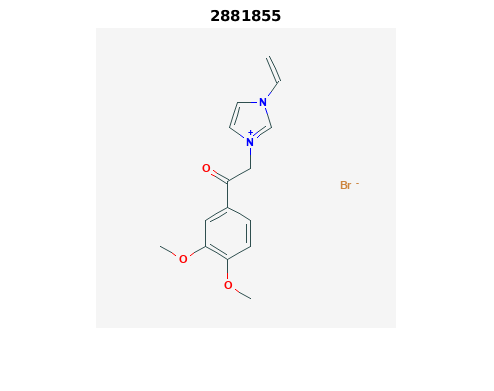

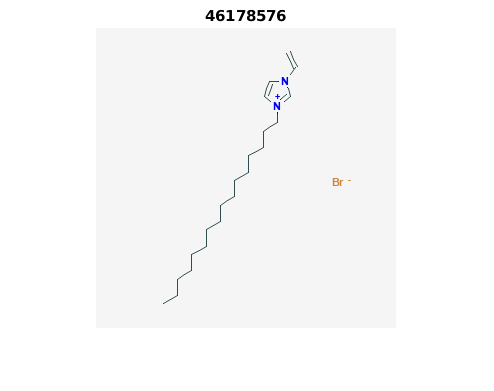

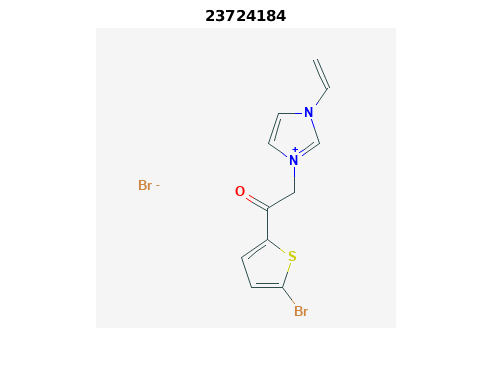

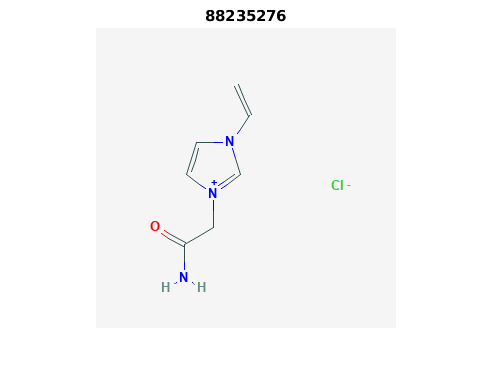

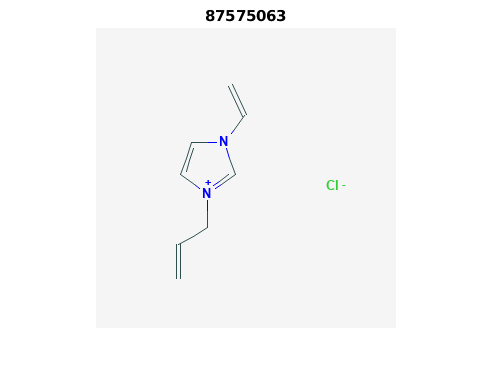

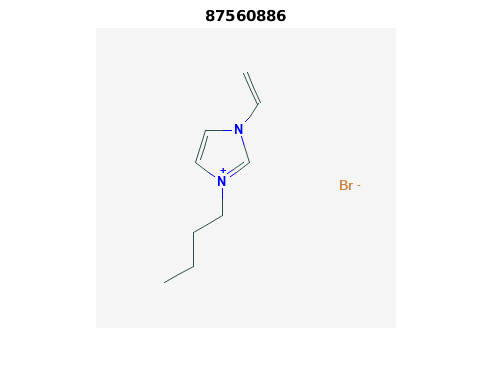

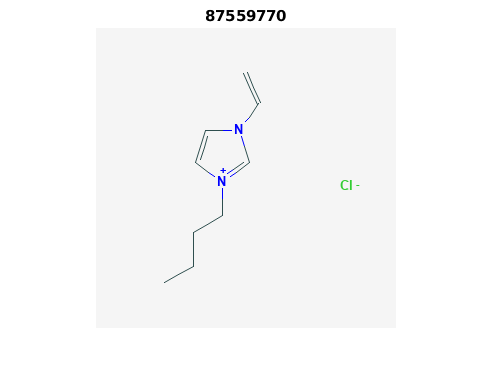

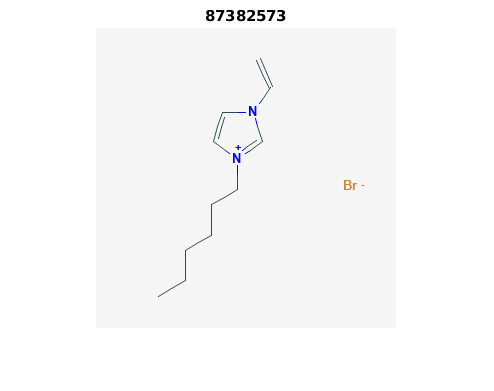

% loop through CIDs and show images
for r = 1:length(hit_CIDsALL)
    CID = hit_CIDsALL{r};
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_url = [api 'cid/' num2str(CID) '/PNG'];
    
    try
        % retrieve CID PNG image and display
        [CID_img,map] = imread(CID_url);
        figure;
        imshow(CID_img,map)
        drawnow;
        title(num2str(CID));
        
        % be polite to PubChem server
        n = 0.5;
        pause(n);
        
    catch
        disp('CID image not found')
        disp('Execution will continue')
    end
    
end